Test "mean_grayvalue.m"

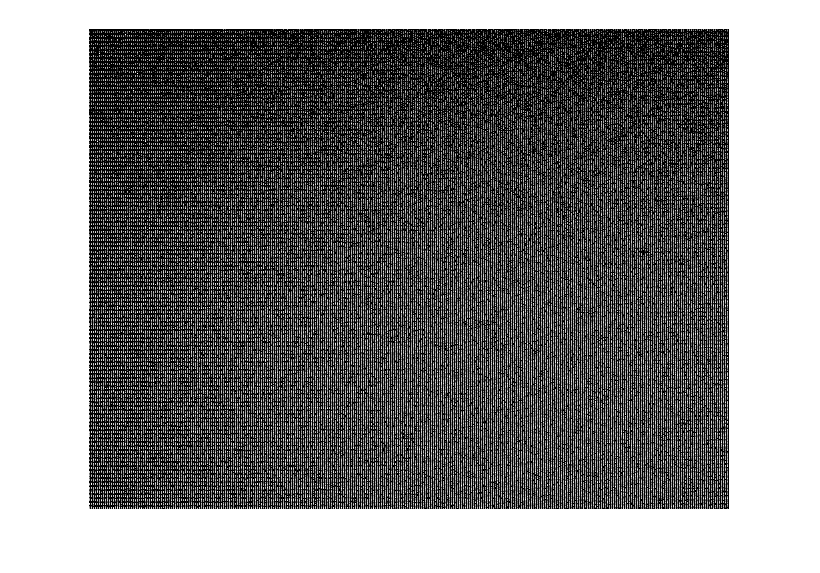

imgA=raw2rgb('mv01-026a.raw');
imgB=raw2rgb('mv01-026b.raw');
imshow(imgA(:,:,1));

mean=mean_grayvalue(imgA(:,:,1),imgB(:,:,1));
mean

mean = 1.4995e+04

imgC=rgb2gray(imgA)

imgC = 480×640 uint16 matrix
    9591    9782   13870   10173   14972    9782   12043   10134   17739   10110   14213   10235   12414    9687   11999    9972   10871   10061   11109   10157   12767   10191   12528    9782   16516   10138   11083    9782   13108    9879   15728   10173   14983    9879   17480    9782   13738    9972   12890   10321   15554   10191   13981    9687   12900    9879   17726    9782   16077   10244
   14972    9782   17919   10173   18477    9782   15925   10134   23563   10110   14515   10235   15535    9687   16302    9972   16264   10061   17515   10157   15719   10191   15037    9782   14918   10138   14095    9782   17606    9879   13673   10173   14152    9879   11977    9782   16057    9972   12449   10321   14242   10191   14096    9687   16640    9879   14621    9782   17829   10244
   25218   10247   17135   10337   21762    9687   24994   10515   29111   10247   26967    9879   35510    9879   32284   10689   29721   11026   25487   10859   29784 

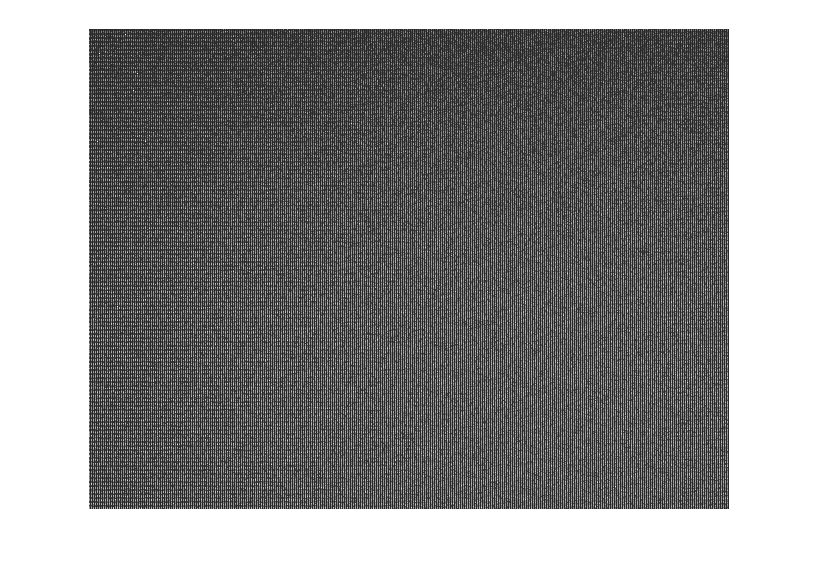

imshow(imgC)

Test "temporalvariance_grayvalue.m"

temporalvargrv=temporalvariance_grayvalue(imgA(:,:,1),imgB(:,:,1));
temporalvargrv

temporalvargrv = 6.1296e+07

Test "saturation.m"

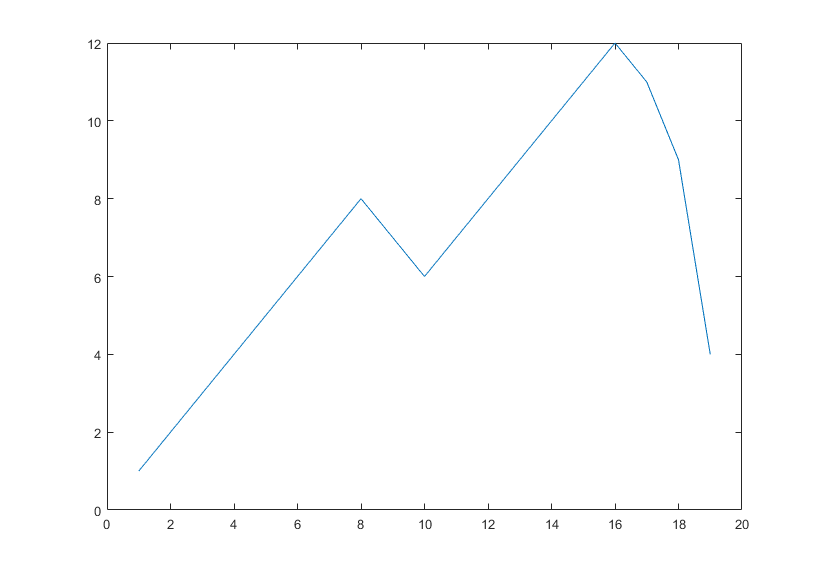

var=[1,2,3,4,5,6,7,8,7,6,7,8,9,10,11,12,11,9,4];
mgv=[1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19];
plot(mgv,var);

[mgv_sat,var_sat]=saturation(mgv,var)

mgv_sat = 16

var_sat = 12

Test "loadRAWinRGBarray"

imgarr=loadRAWinRGBarray('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_mv');
imshow(imgarr{1});

class(imgarr{1})
size(imgarr{1})
length(imgarr)
imgarr{10}(:,:,3)

`Test "photonTransfer_curve_EMVA1288_color" (unvollständige Funktion)`

% [mean_dark,var_dark]=photonTransfer_curve_EMVA1288_color(imgarr)

Test "loadRAWinArray_mono"

imgarray=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_mv',640,480)

imgarray = 1×102 cell array
    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480 uint16}    {640×480

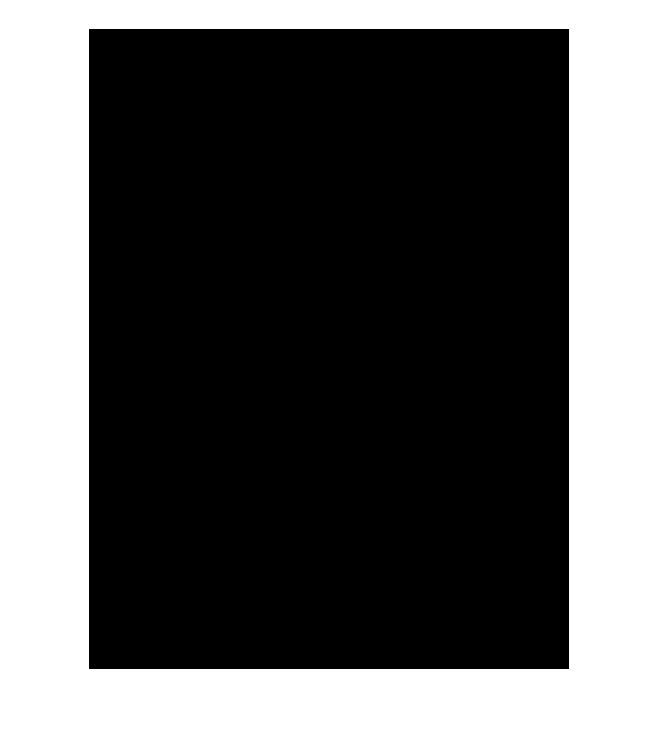

imshow(imgarray{1})

imgarray{1}

ans = 640×480 uint16 matrix
   32   27   28   29   35   36   26   31   23   29   33   27   28   25   34   33   25   27   21   27   28   28   29   23   33   24   35   25   30   34   35   35   30   29   28   24   31   27   32   30   33   25   26   26   29   28   34   28   29   33
   31   25   36   27   37   28   26   30   37   24   33   30   25   29   31   24   29   28   32   37   30   24   32   34   32   35   34   33   29   32   27   25   30   29   32   29   32   29   20   24   29   29   33   36   33   30   35   30   29   30
   32   27   33   32   29   30   31   35   29   32   24   30   27   27   31   23   26   31   31   32   30   28   35   34   32   32   36   31   30   32   24   31   22   30   29   23   34   34   30   25   27   25   30   34   32   38   27   29   31   29
   35   27   32   31   29   26   30   32   26   30   23   30   26   22   32   26   31   23   30   29   30   26   28   24   28   33   30   25   33   27   26   34   24   30   27   26   29   27   22   26   26   36   33   3

Test "photonTransfer_curve_EMVA1288_mono" (unvollständige Funktion)

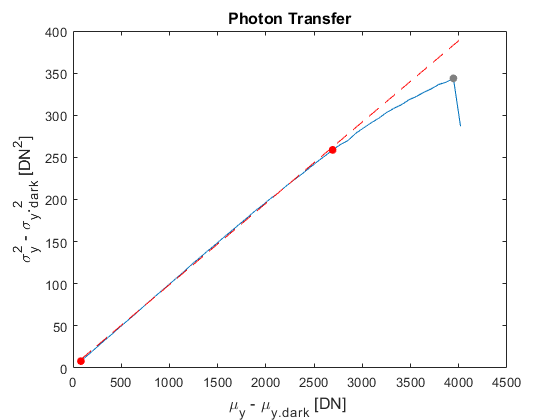

mean_dark = 29.4063

var_dark = 9.0780

K = 0.0966

[mean_dark,var_dark,K]=photonTransfer_curve_EMVA1288_mono(imgarray) 